## 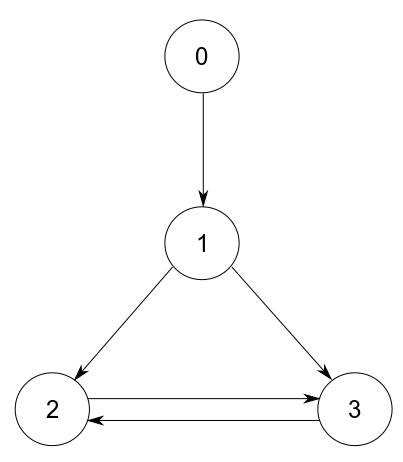

## Systemdefinition


$$\dot{x_i } =\left\lbrack \begin{array}{cccc}
1+\frac{z}{3} & 0 & 0 & 0\\
0 & 0\ldotp 9*\cos \left(0\ldotp 8*z\right) & 0 & 0\\
0 & 0 & -1 & 0\\
0 & 0 & 0 & -3^{-z} 
\end{array}\right\rbrack {x_i }^{\prime } +\left\lbrack \begin{array}{cccc}
0 & 0\ldotp 8 & -1+\frac{z}{4} & 0\ldotp 2\\
\frac{1}{z+1} & 0 & -0\ldotp 4 & 0\\
0 & 0 & 0 & -1\\
-2 & \frac{z}{2} & 0 & 0
\end{array}\right\rbrack x_i$$



$$\begin{array}{l}
x_i^+ \left(0\right)=\left\lbrack \begin{array}{cc}
1 & 0\ldotp 2\\
0 & 1
\end{array}\right\rbrack x_i^- \left(0\right)\\
x_i^- \left(1\right)=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 0\ldotp 6
\end{array}\right\rbrack x_i^+ \left(1\right)+u_i 
\end{array}$$



$$y_i =\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0
\end{array}\right\rbrack x_i \left(0\right)$$


zDomain = quantity.Domain("z", linspace(0, 1, 101));
syms z t;
Lambda = quantity.Symbolic(diag([1+z/3, 0.9*cos(0.8*z), -1, -3*exp(-z)]), zDomain, "name", "Lambda");
A = quantity.Symbolic([0, 0.8, -1+z/4, 0.2; 1/(z+1), 0, -0.4, 0; 0, 0, 0, -1; -2, z/2, 0, 0], zDomain, "name", "A");
Q0 = [1, 0.2; 0 1];
Q1 = [1 0; 0 0.6];

output = model.Output("controlOutput", "C0", [1 0 0 0; 0 1 0 0]);

adjacencyMatrix = [0 0 0 0; 1 0 0 0; 0 1 0 1; 0 1 1 0];

G1 = quantity.Symbolic([0, 0; 0, 0; 0, 0; 0, 0], zDomain, "name", "G1");
G2 = [0, 0; 0 0];
G3 = [1, 0; 0 0];
G4 = [0, 0; 0 0];

mas = MultiAgent(adjacencyMatrix, Lambda, "A", A, "output", output, ...
    "Q0", Q0, "Q1", Q1, "G1", G1, "G2", G2, "G3", G3, "G4", G4);

## Simulation

Simulation des ungeregelten, ungestörten Systems

Plot des Verlaufs der Zustände

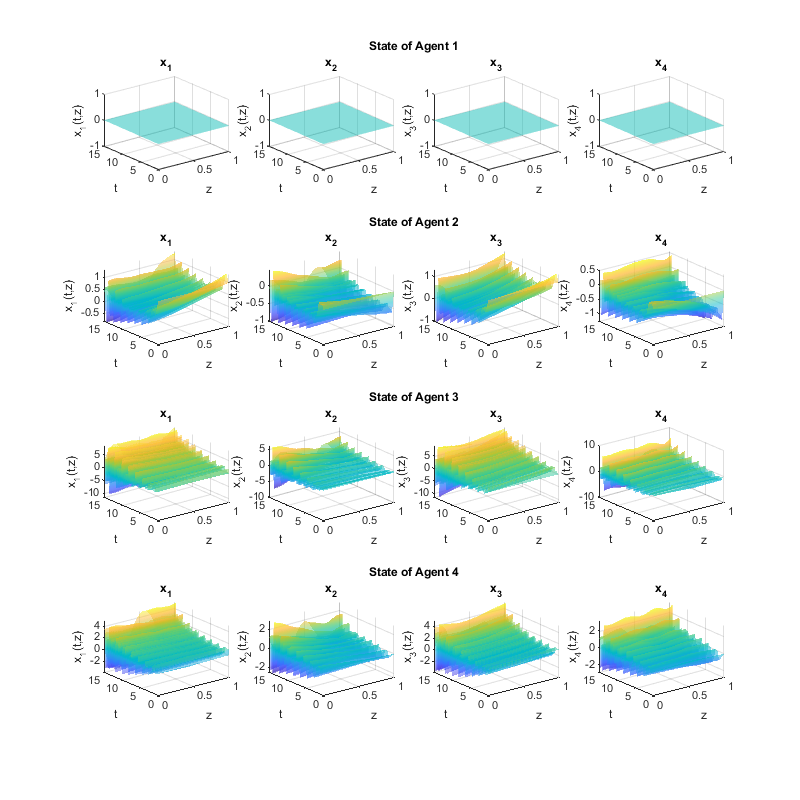

simTime = 15;
tDomain = quantity.Domain("t", linspace(0, simTime, simTime*200+1));
simulationSetting = {'t', tDomain.grid};
ic = {"agent1.x", quantity.Symbolic(zeros(4, 1), zDomain),...
    "agent2.x", quantity.Symbolic([1; 0; 1; 0], zDomain),...
    "agent3.x", quantity.Symbolic([2; -0.5; 0; 0], zDomain),...
    "agent4.x", quantity.Symbolic([0; 0; 1; 0], zDomain)};

simDataRaw = mas.simulate(simulationSetting, ic);

mas.plotState(simDataRaw);

Plot der Ausgangssignale

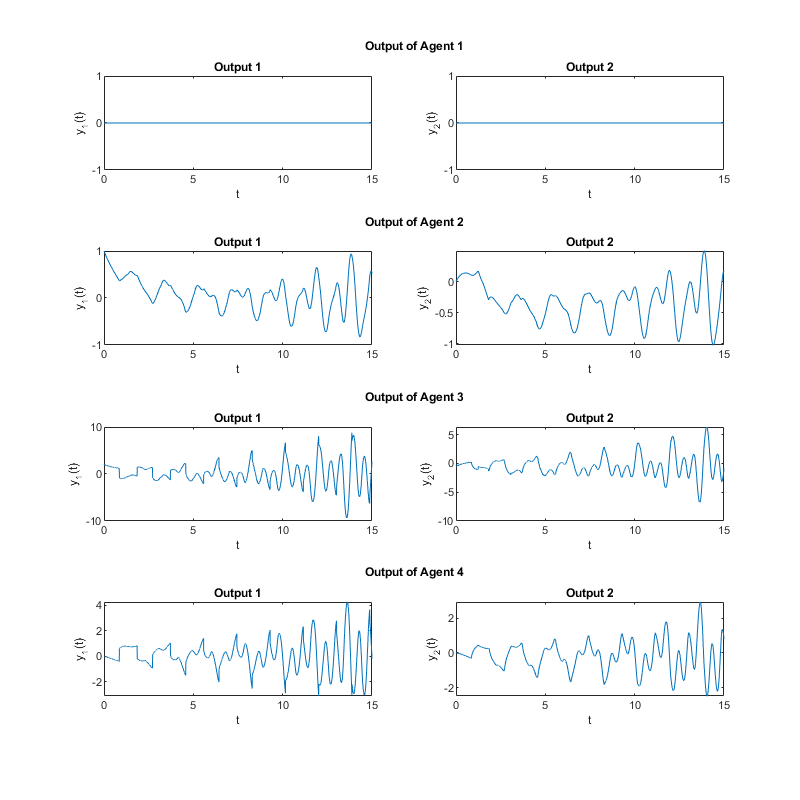

mas.plotOutput(simDataRaw);

## 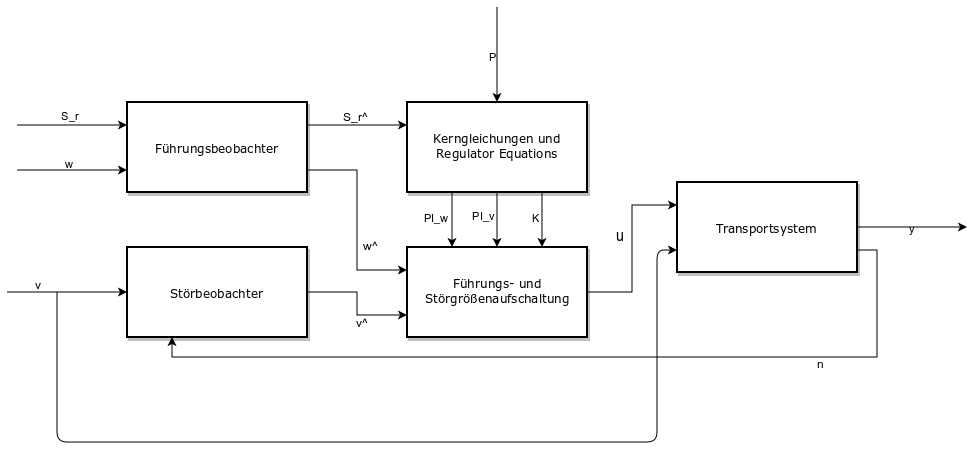

## Führungsbeobachter

S_r = [0 1; -1 0];
w = quantity.Discrete([sin(tDomain.grid), cos(tDomain.grid)], tDomain);

arf = ReferenceObserver(adjacencyMatrix, 2, 3, 3, 3, 3, [1 0; 0 0]);
simDataRef = arf.simulate(w, S_r);

Plot des beobachteten Störzustands

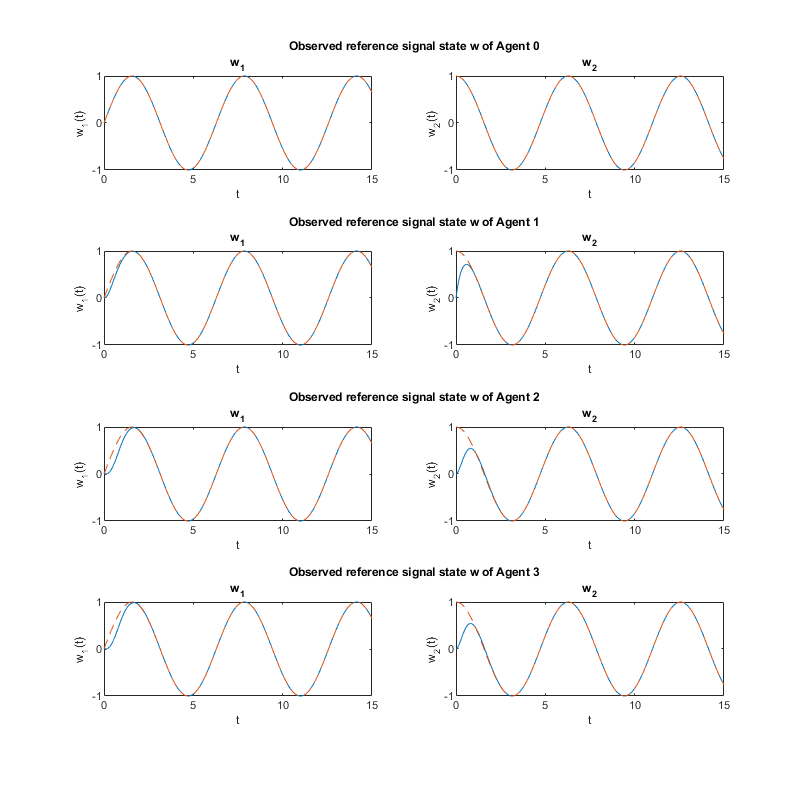

arf.plotObservation(simDataRef);

## Controller Design und Reference Tracking

for indAgent = 1:mas.N
    S_rObs.("agent" + indAgent) = simDataRef.("agent" + (indAgent-1)).S;
end
P_r = eye(2);
tic
[systemTarget, controller] = mas.feedforwardControl(S_rObs, P_r, [0 1; -1 0], eye(2));

## Load the kernel build\kernel\17F558000C0B026B5B102B92300525C51E14A02F.mat from disk...


Dauer des Controller Designs

toc

Elapsed time is 29.655618 seconds.



exogenousSignals = {"agent1.reference", w, "agent2.reference", w, "agent3.reference", w, "agent4.reference", w};
simDataControl = mas.simulate(simulationSetting, ic, controller, exogenousSignals);

Ausgabe des geregelten Systems

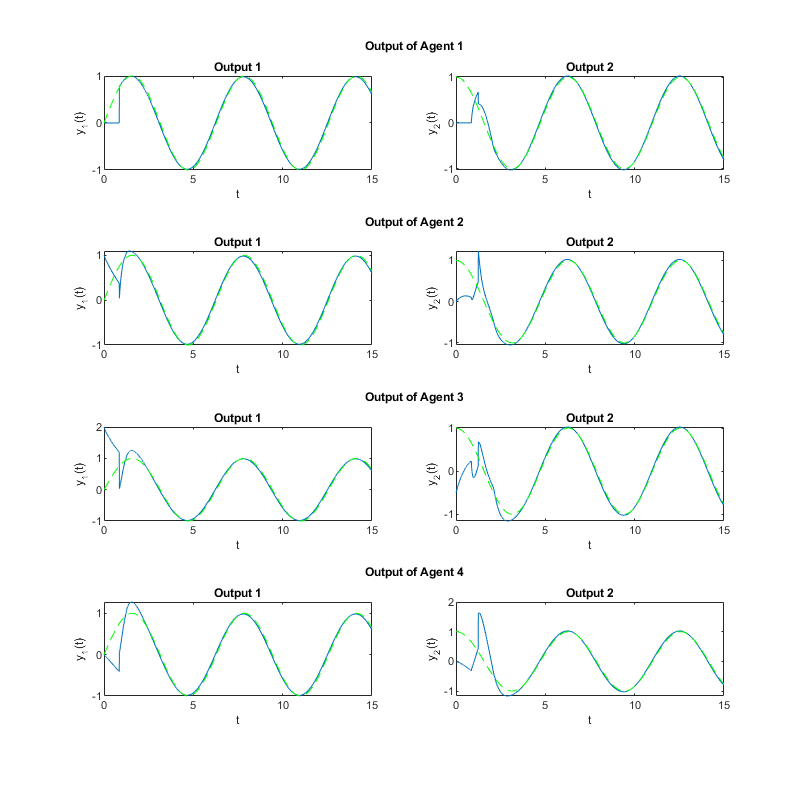

mas.plotOutput(simDataControl);

## Analysiere Lösung der Regulator Equations

Einsetzen von PI_w in die Regulator Equations

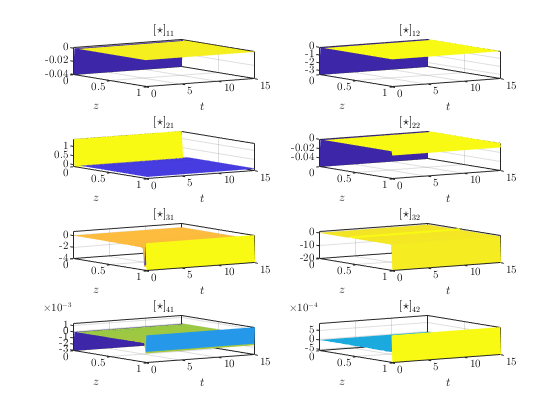

ans = 0.0643

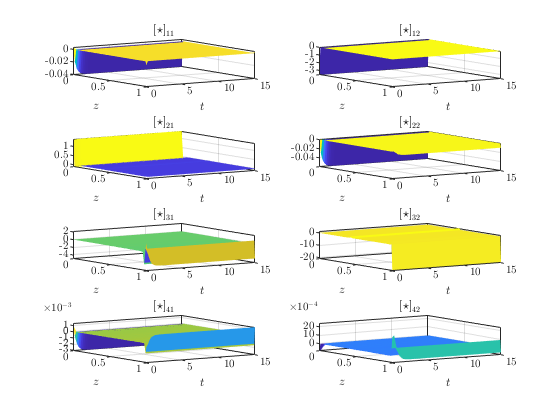

ans = 0.0643

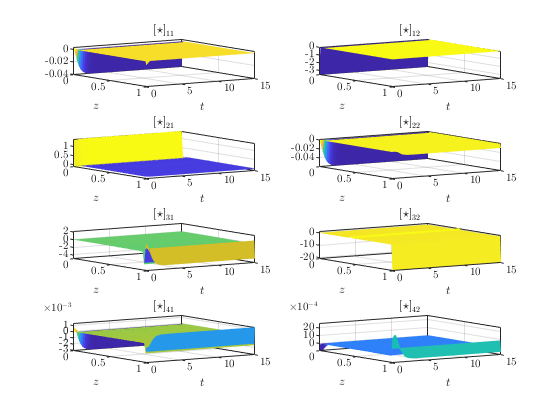

ans = 0.0643

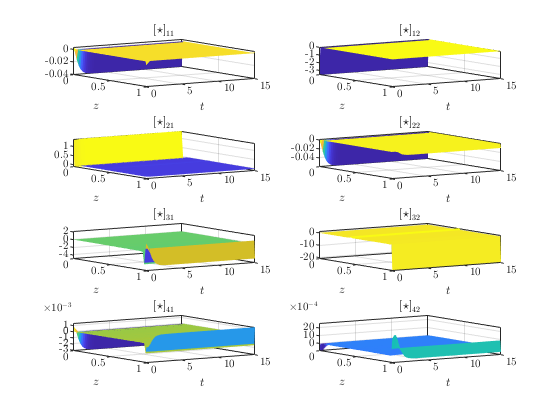

ans = 0.0643

for indAgent = 1:mas.N
   PI_w = controller.PI_w.("agent"+indAgent);
   shouldBeZero = Lambda * diff(PI_w, "z") + controller.backsteppingKernel.getA0Target()*mas.E1.'*subs(PI_w, "z", 0) - PI_w * S_rObs.("agent" + indAgent);
   plot(shouldBeZero);
%    plot(mas.E2.'*subs(PI_w, "z", 0) - mas.Q0*mas.E1.'*subs(PI_w, "z", 0));
%    plot(mas.output.backstepping(controller.backsteppingKernel, "inverse", true).out(PI_w) - P_r);
   max(median(shouldBeZero), [], 'all')
%    max(median(mas.E2.'*subs(PI_w, "z", 0) - mas.Q0*mas.E1.'*subs(PI_w, "z", 0)), [], 'all')
%    max(median(mas.output.backstepping(controller.backsteppingKernel, "inverse", true).out(PI_w) - P_r), [], 'all')
end

Vergleich mit Chebyshev-Methode

tic
PI_wCheb = tool.solveGenericBvpFirstOrderCheb(S_r, Lambda, quantity.Discrete.zeros([4, 4], zDomain),...
                quantity.Discrete.zeros([4, 2], zDomain), controller.backsteppingKernel.getA0Target(),...
                Q0, zeros(2, 2), output.backstepping(controller.backsteppingKernel, "inverse", true), P_r);
toc

Elapsed time is 0.442152 seconds.


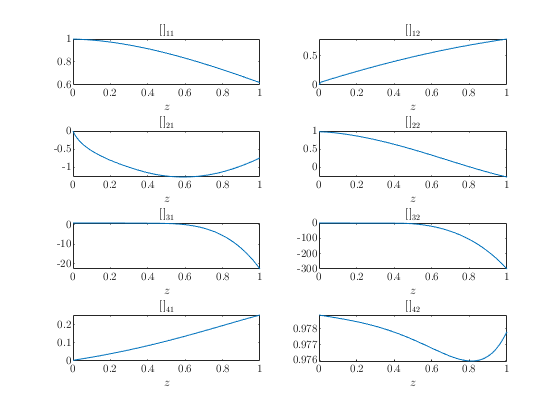

plot(PI_wCheb);

tic
PI_wSeries = mas.solveRegulatorEquationReferenceExplicit(S_r, P_r);
toc

Elapsed time is 1.375204 seconds.


Differenz der beiden Lösungen

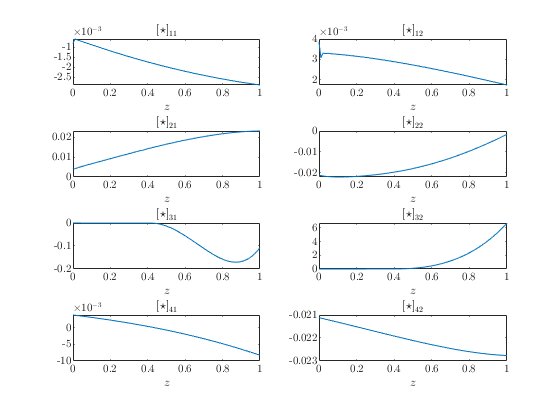

plot(PI_wCheb - PI_wSeries);

## Tracking a changing Reference Signal

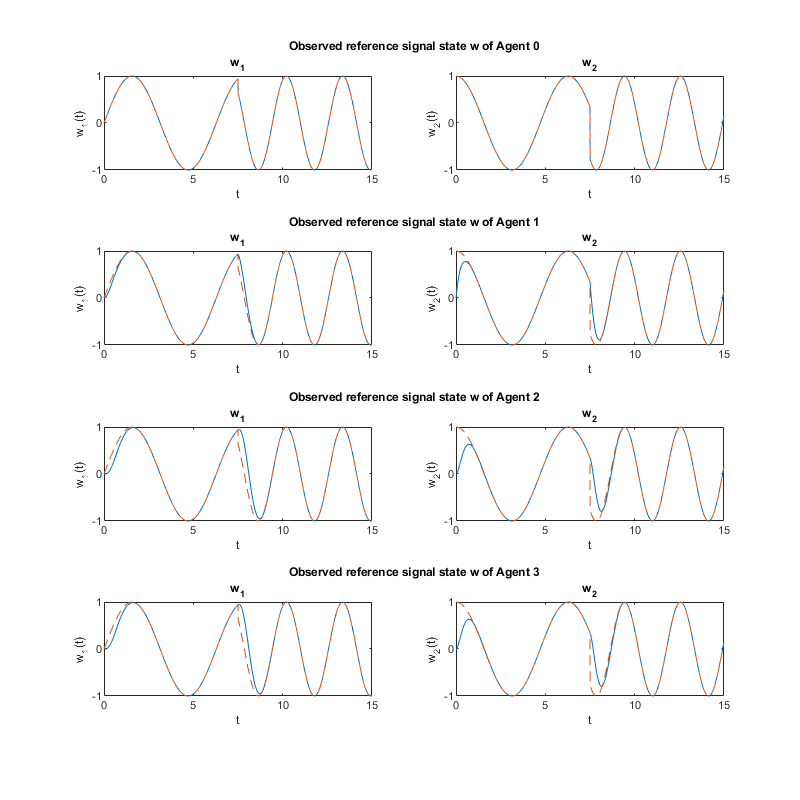

splitDomain = tDomain.split(simTime/2);
S_r = quantity.Piecewise({[0 1; -1 0] * quantity.Discrete.ones(1, splitDomain(1)), [0 2; -2 0] * quantity.Discrete.ones(1, splitDomain(2))});
S_r = quantity.Discrete(S_r);
w = quantity.Piecewise({quantity.Discrete([sin(splitDomain(1).grid), cos(splitDomain(1).grid)], splitDomain(1)), ...
    quantity.Discrete([sin(2*splitDomain(2).grid), cos(2*splitDomain(2).grid)], splitDomain(2))});
w = quantity.Discrete(w);

arf = ReferenceObserver(adjacencyMatrix, 2, 4, 4, 4, 4);

simDataRef = arf.simulate(w, S_r);
arf.plotObservation(simDataRef);


for indAgent = 1:mas.N
    S_rObs.("agent" + indAgent) = simDataRef.("agent" + (indAgent - 1)).S;
end

[systemTarget, controller] = mas.feedforwardControl(S_rObs, [1 0; 0 1], [0 1; -1 0], eye(2));

## Load the kernel build\kernel\17F558000C0B026B5B102B92300525C51E14A02F.mat from disk...


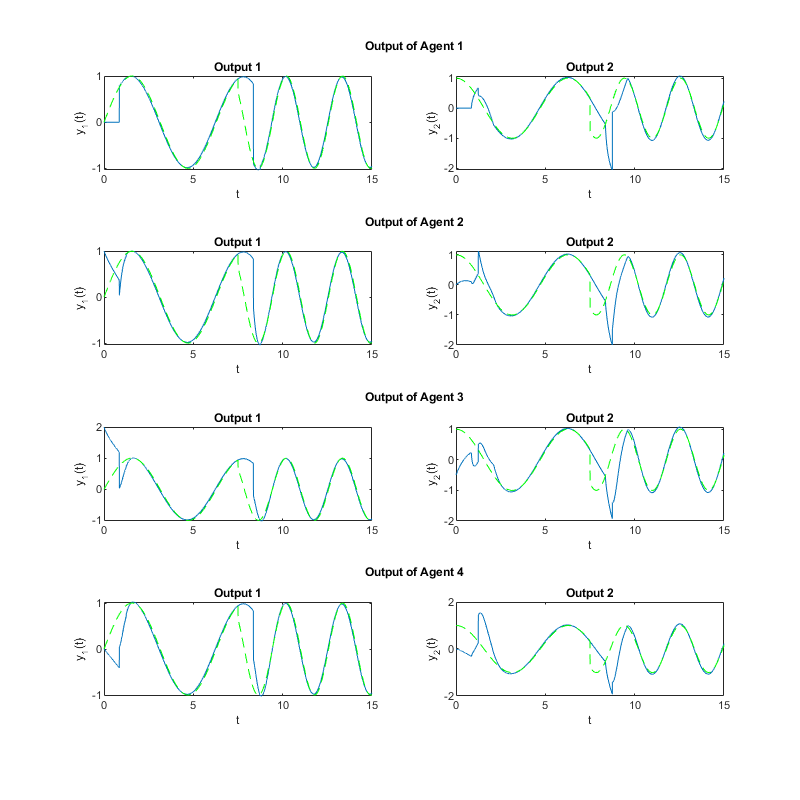


exogenousSignals = {"agent1.reference", w, "agent2.reference", w, "agent3.reference", w, "agent4.reference", w};
simDataControl = mas.simulate(simulationSetting, ic, controller, exogenousSignals);

mas.plotOutput(simDataControl);

## Disturbance Observer

simTime = 25

simTime = 25

tDomain = quantity.Domain("t", linspace(0, simTime, simTime*200+1));
simulationSetting = {'t', tDomain.grid};
S = [0 1; -1 0];
P = eye(2);

v = quantity.Discrete([sin(tDomain.grid), cos(tDomain.grid)], tDomain);
zer0 = v * 0;
distObserver = DisturbanceObserver(mas, S, P, "c_", 10);

## Load the kernel build\kernel\2F17AD94CBC6AD5BC20FAB42506661327292F395.mat from disk...
Successive Calculation of inverse of c flip({flip(Lambda)^{-1}  flip(Lambda)}^{T}):  21 of max. 50 change = 2.7952e-05
 Elapsed time 9.53 seconds 


dAgg = [zer0; v; zer0; v];
exogenousSignals = {"disturbance", dAgg};
simDataDist = mas.simulate(simulationSetting, ic, struct(), exogenousSignals, distObserver);

figure;
for indAgent = 1:mas.N
    for indDim = 1:length(v)
        ax = subplot(mas.N, length(v), (indAgent - 1)*length(v) + indDim);
        simDomain = simDataDist.("agent" + indAgent).observer.disturbanceState.domain;
        plot(simDomain.grid, simDataDist.("agent" + indAgent).observer.disturbanceState(indDim).valueDiscrete);
        hold on; 
        d = dAgg((indAgent - 1)*length(v) + 1 : indAgent * length(v));
        plot(simDomain.grid, d(indDim).valueDiscrete, '--g');
        hold off;
    end
end